# Does V1 response suppression initiate binocular rivalry?

Welcome to the controller live-script for figure generation of the BRFS manuscript as submitted to iScience.

As Cell Press authors, we share all of the data and original code we report in our paper with the research community. This live-script plots the figures reported in the associated manuscript at iScience. The data have been published on Zenodo: 

#### Carlson, Brock, M., Mitchell, Blake, A., Kacie Dougherty, Westerberg, Jacob, A., & Maier, Alexander. (2023). Does V1 response suppression initiate binocular rivalry?. Iscience. https://doi.org/10.5281/zenodo.7951315

This script is dependent on Gramm which can be found at https://github.com/piermorel/gramm

This notebook processes our event-locked data, uses Gramm to plot continuous data, and then formats datastructures of subsequent stastical analysis in JASP.

## Step 1: Download the data from Zenodo

There is not a programatic integration between Zenodo and MATLAB. You may manually download the data via the following steps:

- Navigate to this publications data directory:  [https://zenodo.org/record/7951315](https://zenodo.org/record/7951315)

- Create a data folder to be accesed by this script such as: C:\ ... \MATLAB\BMC_AdaptdcosFigures

- Download all data to this directory. Total file size is 4.0GB.

## Step 2: Set up root directory

ROOTDIR = 'C:\Users\Brock Carlson\Documents\MATLAB\BMC_AdaptdcosFigures\';
cd(ROOTDIR)

## Step 3: Individual unit classification

To obtain multiunit activity (MUA) from the broadband signal, we low-pass filtered the 30kHz-sampled voltage signals at 5 kHz with a bidirectional Butterworth filter. We then down sampled by a factor of 3, followed by application of a second-order bidirectional Butterworth filter to high-pass filter at 1kHz. We then rectified the resulting data, and down sampled by another factor of 3. To detect impulses (spikes) in the MUA signal, a time-varying threshold enveloped the broadband signal. An impulse was recorded whenever the signal exceeded a pre-set threshold of 2.2 times the noise floor. The threshold was computed after smoothing the signal. Signal smoothing was achieved by convolving the data with a 12s boxcar. 

The MUA signal is triggered to each photo diode onset of a successful trial. Metadata and triggered continuous data are contained in the STIM structure for each file's sesion. We can now organize the data in a condition-specific format and evaluate each multi-units individual tuning characteristics (namely ocular dominance and orientaiton preference).

%% Individual Unit Classification
[IDX,ERR] = IDX_iScienceSubmission(ROOTDIR)

## Step 4: Plot data using [Gramm](https://github.com/piermorel/gramm)

To obtain multiunit activity (MUA) from the broadband sign


cd(FORMDATDIR)
dataFileName = 'carlsonEtAl_iScienceFigs_allTunedUnits';
load(strcat(FORMDATDIR,strcat(filesep,dataFileName,'.mat')))



Now we create images with Gramm.

ans =   1×2 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


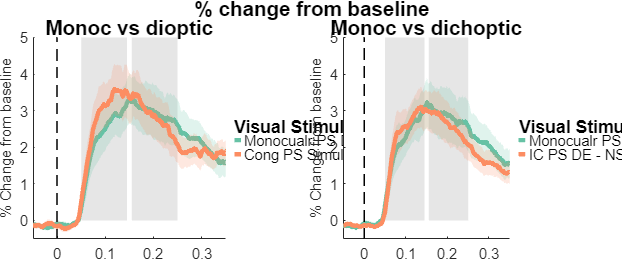

% IDX breakdown
numUnits = idxBreakdown(IDX,ERR);

%% Figure 2a and 2b

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


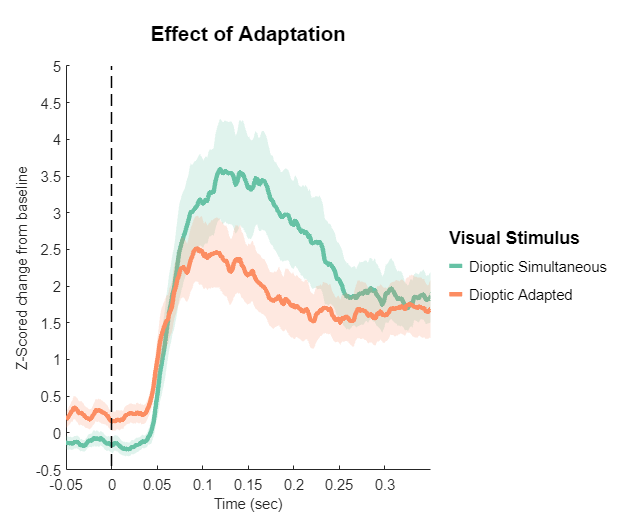

gramm_dCOS_line(IDX);

% Figure 2c

ans =   1×2 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


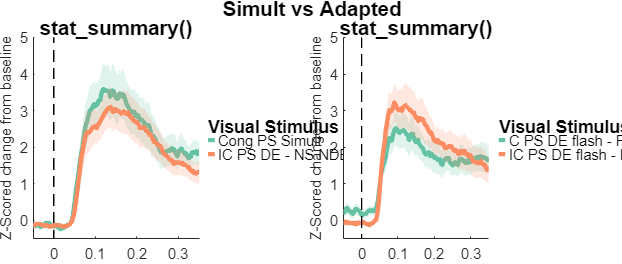

gramm_adaptation_line(IDX)

% Figure 3

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


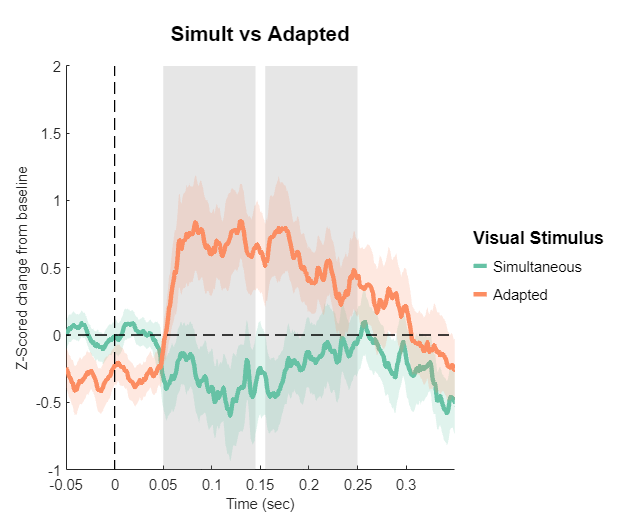

gramm_2x2_line(IDX)

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


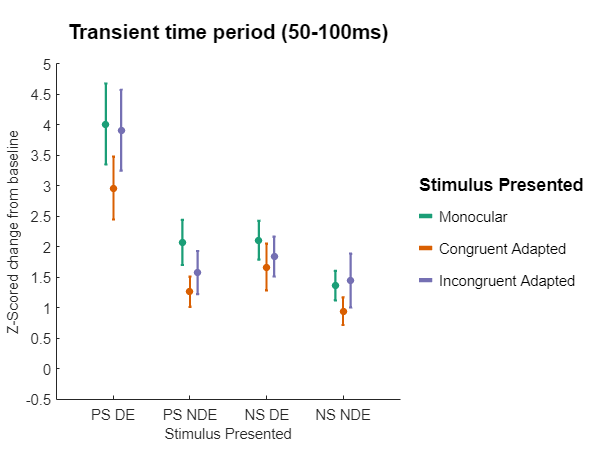

gramm_2x2_subline(IDX)

% Figure 4

gramm_adaptationEffect(IDX)


## Step 2: format data for JASP

Next we format the IDX output into a .csv that JASP can accept

Because we are running a repeated measures t-tests and a repeated measures ANOVA, the results must be formateed (A x B) where A is each unit and B are the various conditions possible. The contents of each cell is the average response (within a given time-window) for a given unit to all presentations of that column's condition. Note that there will be missing conditions for each unit because not all conditions were shown on any individual day. Furthermore, while the condition shown to the subjects were selected for the majority of unit preferences on any given day, there are frequently a few units tuned to the ipsilateral eye and orthagonal orientation. Because preferences are established from the unit's perspective, some units will not have the prefered stimulus shown to the dominant eye. JASP does a good job of tracking and correcting for missing values. You can select to ignore missing values listwise or conditionwise. Typically, it is best practice to ignore missing values listwise to keep the degrees of freedomn identical between contrasts.

%% JASP conversion
% JASP requires each unit to be in a row vector with each column as the
% different conditions.
% Currently each row of IDX.allV1 is for its own unit (that's good).
% IDX.allV1.RESP_avg contains a 24x1 cell, where each cell contains the
% average for all 4 time periods of the RESP vector. 
% We have 24 potential conditions
% The output required are 88 x 24 arrays.
% We need 1 array for the transient period and 1 array for the sustained.
% win_ms is [transient, sustained, whole time, baseline]

numberOfUnits = size(IDX.allV1,2);

for i = 1:numberOfUnits
    for j = 1:24
        outputForJASP_transient(i,j) = IDX.allV1(i).RESP_avg{j}(1);
        outputForJASP_sustained(i,j) = IDX.allV1(i).RESP_avg{j}(2);
    end
end

%% Writetable
% Now we need to export these values to .csv for JASP import. It would be
% great if I did not have to input 24 condition labels by hand

conditionLabels = IDX.allV1(1).condition;
conditionNames = conditionLabels.Properties.RowNames;
outputForJASP_transient_table = array2table(outputForJASP_transient);
outputForJASP_sustained_table = array2table(outputForJASP_sustained);

outputForJASP_transient_table.Properties.VariableNames = conditionNames;
outputForJASP_sustained_table.Properties.VariableNames = conditionNames;

cd(FORMDATDIR)
    saveNameTrans = strcat('JASP_transient','.csv');
    saveNameSus     = strcat('JASP_sustained','.csv');
    writetable(outputForJASP_transient_table,saveNameTrans)
    writetable(outputForJASP_sustained_table,saveNameSus)